**第9讲 非线性方程（组）求解**

### **9.1**  `二分法`

#### **9.1.1**  `二分法的``特点`

        `在求方程近似根的所有方法中，二分法是非线性方程求解最直观、最简单的方法。它是通过将非线性方程`f(x)`的零点所在小区间逐次收缩一半，使区间的两个端点逐步逼近函数的零点，以求得函数零点的近似值得方法。`

`介值``定理``：若函数`f(x)`在`[a,b]`上``连续且`f(a)f(b)<0`，则方程`f(x)=0`在`[a,b]`上必有一根`x*`。`

#### **9.1.2 **`二分法基本原理`

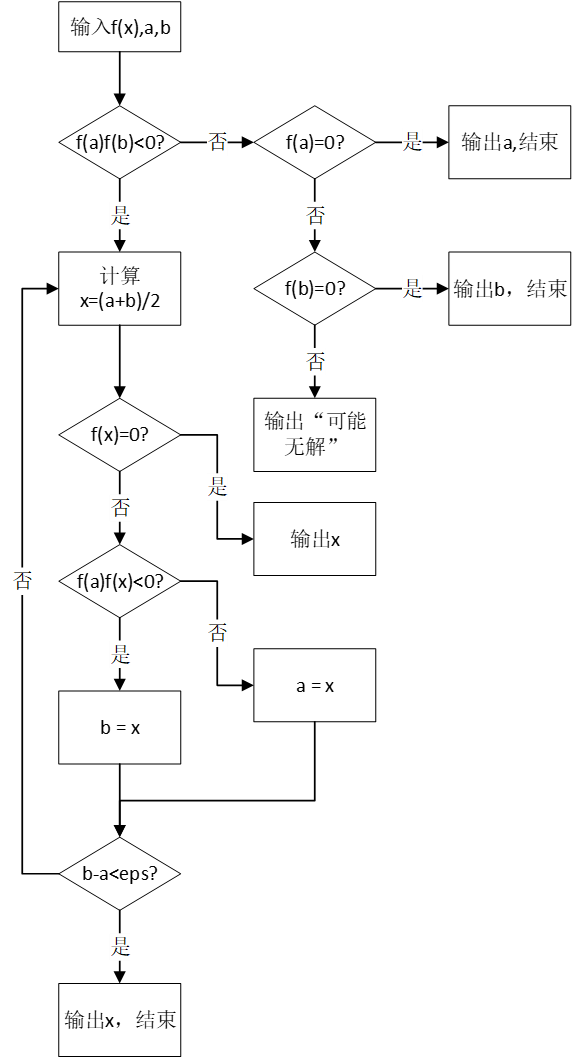   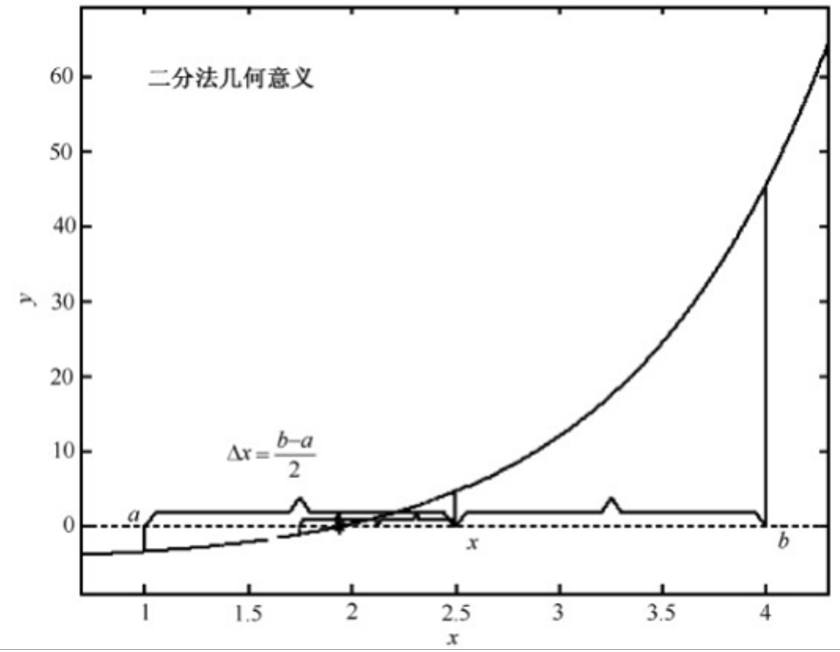

#### **9.1.3**`二分法求解代码实现`

`函数文件： bisect.m`

`function [x,fx,iter,X]=bisect(fun,a,b,eps,varargin)`

`% 二分法求解非线性方程的根`

`% 输入参数：`

`%      ---fun：待求根方程的函数描述`

`%      ---a,b：初始区间的端点`

`%      ---eps：精度要求，默认值为1e-6`

`%      ---p1,p2,...：求根函数附加参数`

`% 输出参数：`

`%      ---x：非线性方程的近似根`

`%      ---fx：根x处的函数值`

`%      ---iter：迭代次数`

`%      ---X：每一步迭代的结果`

`if nargin<3,error('输入参数至少需要3个！'),end`

`if nargin<4|isempty(eps),eps=1e-6;end`

`fa=feval(fun,a,varargin{:});fb=feval(fun,b,varargin{:});`

`% fa=fun(a,varargin{:});fb=fun(b,varargin{:});`

`k=1;`

`if fa*fb>0  % 不满足二分法使用条件`

`    warning(['区间[',num2str(a),',',num2str(b),']内可能没有根']);`

`elseif fa==0  % 区间左端点为根`

`    x=a;fx=fa;`

`elseif fb==0  % 区间右端点为根`

`    x=b;fx=fb;`

`else`

`    while abs(b-a)>eps;  % 控制二分法结束条件`

`        x=(a+b)/2;  % 二分区间端点`

`        fx = feval(fun,x,varargin{:}); % 计算中点的函数值`

`        if fa*fx>0;  % 条件`

`            a = x;   % 端点更新`

`            fa = fx;  % 端点函数值更新`

`        elseif fb*fx>0;  % 条件`

`            b = x;  % 端点更新`

`            fb = fx;  % 端点函数值更新`

`        else`

`            break`

`        end`

`        X(k)=x;k=k+1;`

`    end`

`end`

`iter=k;`

`==========================================`

`该函数调用格式：   [x,fx,iter,X] = bisect(fun,a,b,eps,p1,p2,...)`

`示例 1 ：`

`利用二分法求解humps函数在区间[0,2]的零点，其中humps函数是MATLAB自带函数，其数学表达式为`

调用上线编写的bisect()函数，进行二分法求解。

求解过程代码为：

clear
clf
x = 0:0.01:2;
fun=@(x)1./((x-.3).^2 +.01)+1./((x-.9).^2 +.04)-6;  % 定义函数表达式
[xx,fx,iter,X]=bisect(fun,0,2,1e-8);  % 二分法求解非线性方程
xx,fx,iter,X

xx = 1.2995

fx = 1.3443e-07

iter = 29

X =     1.0000    1.5000    1.2500    1.3750    1.3125    1.2813    1.2969    1.3047    1.3008    1.2988    1.2998    1.2993    1.2996    1.2994    1.2995    1.2995    1.2995    1.2996    1.2995    1.2996    1.2996    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995


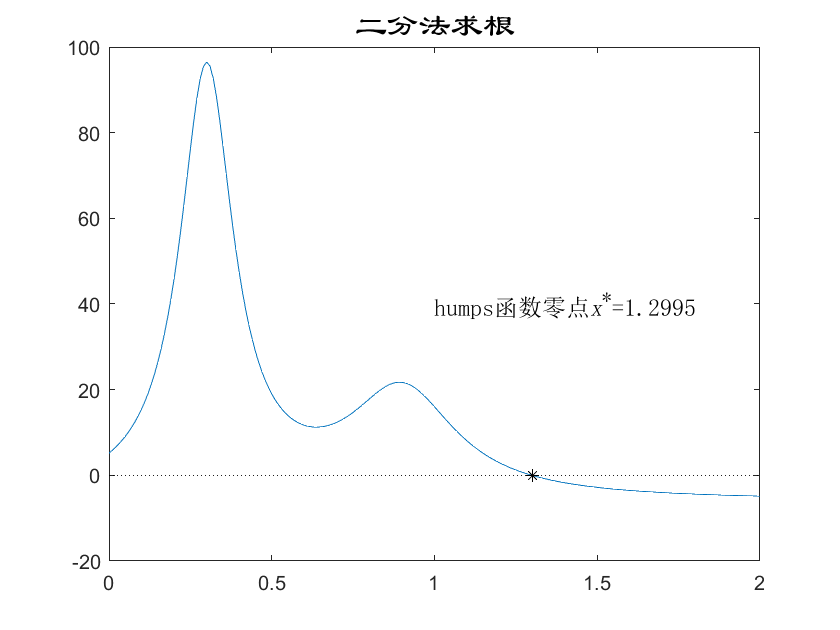

plot(x,humps(x),[0,2],[0,0],'k:',xx,fx,'k*')  % 绘制图形
text(1,40,['humps函数零点{\itx}^*=',num2str(xx)],...
    'fontname','宋体','fontsize',12)  % 添加标注
title('\fontname{隶书}\fontsize{16}二分法求根')  % 添加标题

#### `9.1.4 试位法`

`试位法也称为线性插值法。该方法类似于二分法，但它不是均匀分割区间，而是利用区间两端点进行线性插值，得到与x轴的交点，`

`并将该交点作为一个更精确的根的估计值。`

`插值得到x轴交点的公式为：`

试位法实现流程图：

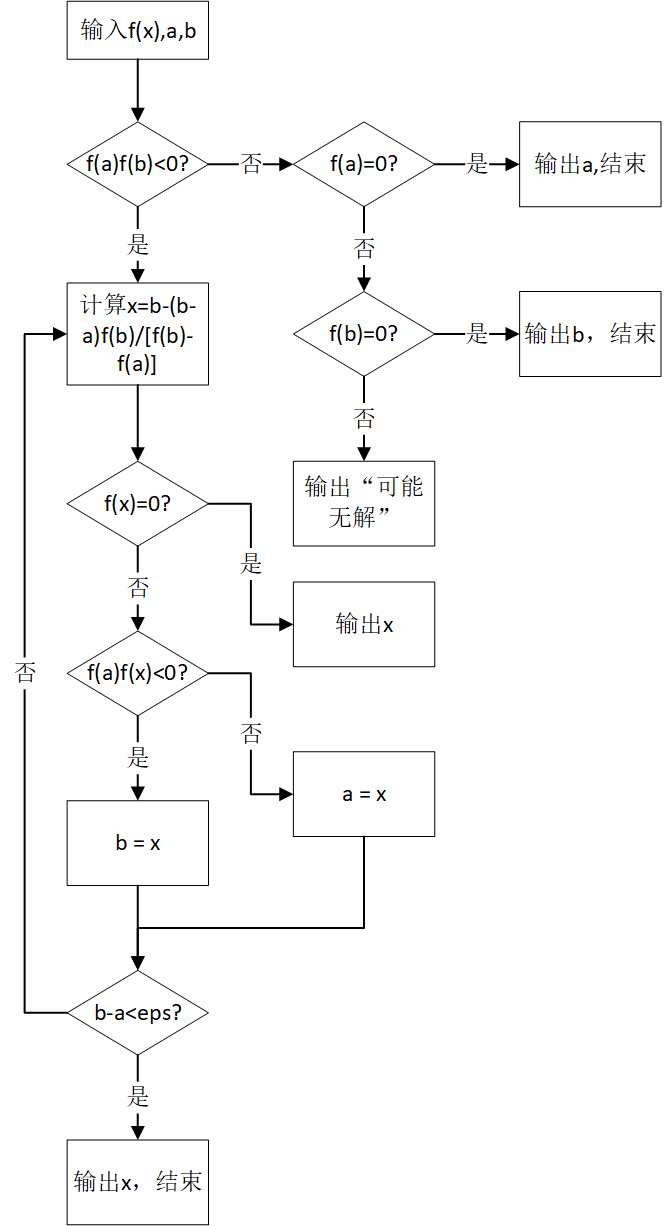

======================================================

**示例2 ： 使用试位法 解示例1：**

clear
clf
x=0:0.01:2;
fun=@(x)1./((x-.3).^2 +.01)+1./((x-.9).^2 +.04)-6;  % 利用内联函数定义函数表达式
[xx,fx,iter,X]=test_bit(fun,0,2,1e-8);  % 试位法非线性方程的根
xx,fx,iter,X

xx = 1.2995

fx = 0

iter = 63

X =     1.0320    1.7403    1.5704    1.4620    1.3947    1.3543    1.3306    1.3170    1.3093    1.3050    1.3026    1.3012    1.3005    1.3001    1.2998    1.2997    1.2996    1.2996    1.2996    1.2996    1.2996    1.2996    1.2996    1.2996    1.2996    1.2996    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995    1.2995


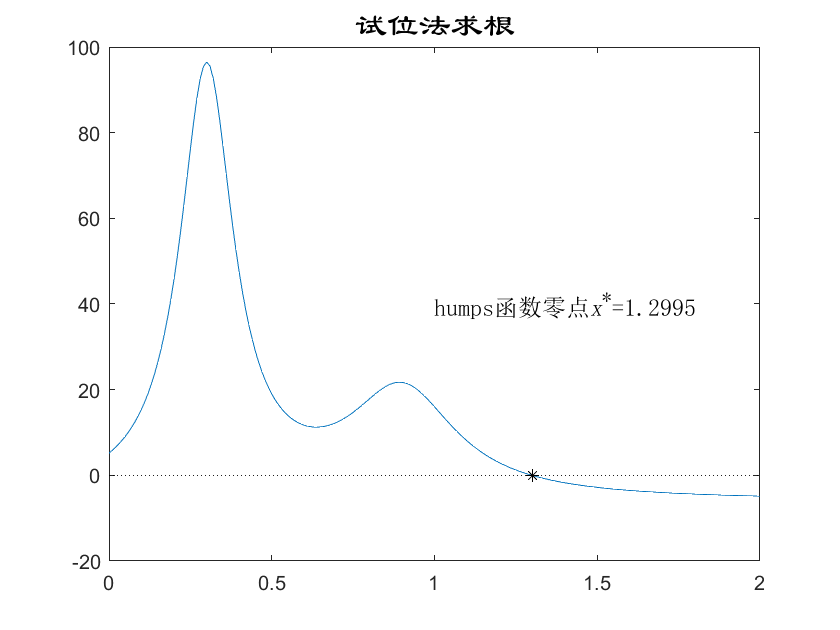

plot(x,humps(x),[0,2],[0,0],'k:',xx,fx,'k*')  % 绘制图形
text(1,40,['humps函数零点{\itx}^*=',num2str(xx)],...
    'fontname','宋体','fontsize',12)  % 添加标注
title('\fontname{隶书}\fontsize{16}试位法求根')  % 添加标题

**二分法与试位法比较：**

1、试位法的效率取决于求解区间函数的线性度；

2、试位法求得的近似根具有误差更小。

3、两种算法均仅求得求解区间内的一个根

### 9.2 简单迭代法

迭代法是数值计算中的一类典型方法，其基本思想是一种逐次逼近的方法。 

首先选取一个初始迭代值，然后由递推公式反复矫正这个初始值，直到满足预先给定的精度要求为止。

#### 9.2.1 简单迭代法基本原理

对于给定的非线性方程f(x)=0,若该方程在区间[a,b]内存在一个根，该方程可以改写为其等价形式： 

φ(x)=f(x)+x

则求解方程根的问题即转换为求解函数φ(x)的不动点问题。

取方程根的某一近似值x0作为初始点，由递推公式$x_{k+1} =\varphi {\left(x_k \right)}$，

可计算出序列$x_k {\left(k=0,1,2,\dots \right)}$，若序列$\mathrm{\ }{{\left\{x_k \right\}}}_{k=0}^{\infty }$收敛，即存在$x^*$使得$\lim_{k\to \infty } x_k =x^*$，又φ(x)在$x^*$附近连续，

则由$\lim_{k\to \infty } x_{k+1} =\lim_{k\to \infty } \varphi {\left(x_k \right)}$可知，$x^* =\varphi {\left(\ x^* \right)}\$，即$x^*$是函数φ(x)的不动点，也就是方程(x)=0的根。

使用简单迭代法时，若在求解区间，f(x)单调递增，则简单迭代法呈现单调逼近模式；

若f(x)单调递减，则简单迭代法呈现螺旋逼近模式。

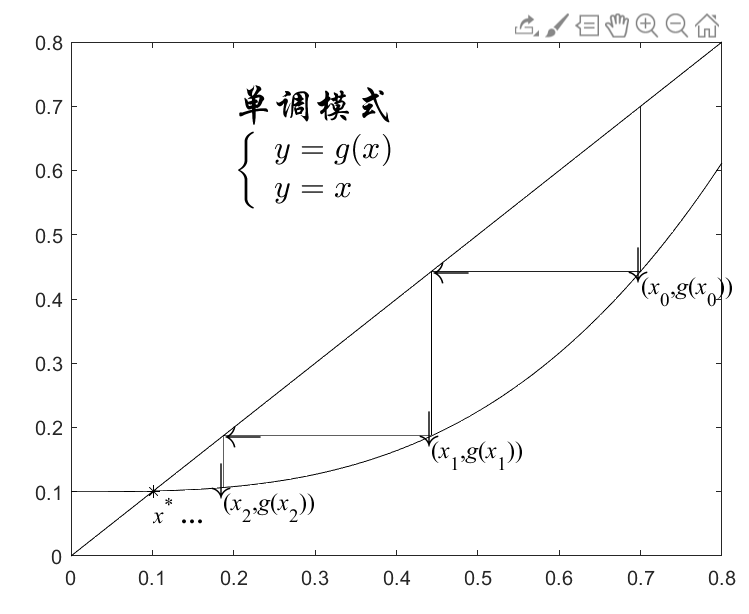   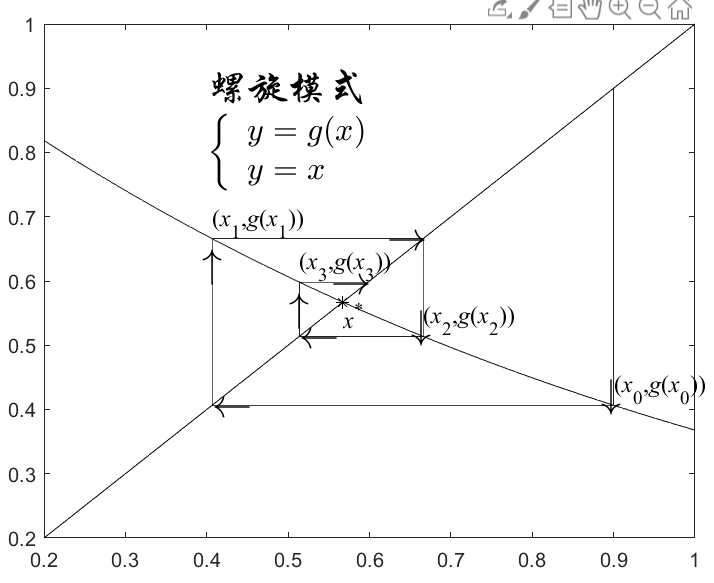

#### 9.2.2 简单迭代法执行流程

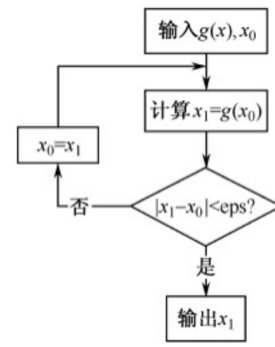

简单迭代法代码实现：

function [x,iter,X]=fixpt(g,x0,eps,maxiter)

% 简单迭代法求非线性方程的根

% 输入参数：

%      ---g：迭代函数

%      ---x0：初始迭代点

%      ---eps：精度要求，默认值为1e-6

%      ---maxiter：最大迭代次数，默认值为1e4

% 输出参数：

%      ---x：非线性方程的近似根

%      ---iter：迭代次数

%      ---X：每一步迭代的结果

if nargin<2,error('输入参数至少需要3个！'),end

if nargin<3|isempty(eps),eps=1e-6;end

if nargin<4|isempty(maxiter),maxiter=1e4;end

err=1;k=0;

while err>eps

    k=k+1;

    x1=feval(g,x0);  % 迭代

x2 = feval(g,x1)

x1  = 

    err=abs(x1-x0);  % 相邻两次的误差

    x0=x1;  % 更新

    X(k)=x1;

    if k==maxiter

        error('迭代次数超限，迭代失败！')

    end

end

x=x1;iter=k;X=X';

=====实例 3========================

**实例3 ** 利用简单迭代法求函数 在1.5附近的零点。

解题过程代码实现：

x=-0.5:0.01:1;
fun=@(x)sin(x)-x.^2+0.5;  % 定义函数表达式
[xx,iter,X]=fixpt(fun,1.5,1e-8);  % 不动点迭代求根
xx,iter,X

xx = 0.6713

iter = 36

X =    -0.7525
   -0.7497
   -0.7435
   -0.7298
   -0.6992
   -0.6326
   -0.4913
   -0.2132
    0.2429
    0.6815


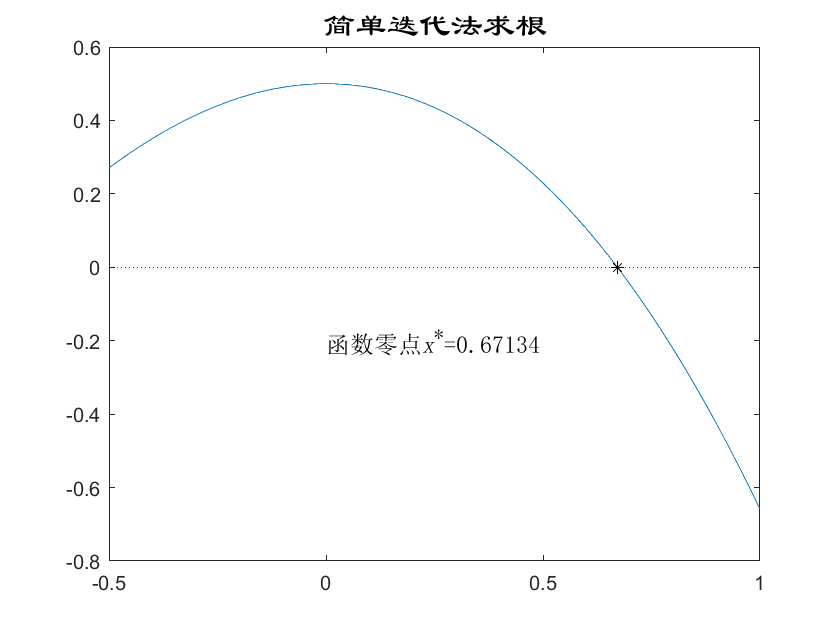

plot(x,sin(x)-x.^2-x+0.5,[-0.5,1],[0,0],'k:',...
    xx,fun(xx)-xx,'k*')  % 绘制图形
text(0,-0.2,['函数零点{\itx}^*=',num2str(xx)],...
    'fontname','宋体','fontsize',12)  % 添加标注
title('\fontname{隶书}\fontsize{16}简单迭代法求根')  % 添加标题

#### 9.2.3 简单迭代法的加速算法——Steffensen加速

对于收敛的迭代过程，只要迭代足够多次，就可以使结果达到任意的精度，但有时迭代过程收敛缓慢，从而使计算量变得很大。

这里介绍一种常用的加速算法——Steffensen加速迭代法，其迭代公式为：

# Steffensen加速法的代码就留个同学们自己去写了。^_^

=================================

**实例4  **分别利用简单迭代法和Steffensen加速迭代法求解函数 f(x) = x^3-x-1在x=3.5附近的根。

从函数f(x)的表达式可以得到两个等价形式： φ(x)=x^3-1 和 $\psi \left(x\right)=\sqrt[3]{x+1}$

基于φ(x)=x^3-1 的简单迭代法是不收敛的，无法搜索到方程的根。

% 针对φ(x)=x^3-1 
x=-2:0.01:2;
f=@(x)x.^3-1;
g=@(x)(x+1).^(1/3);
x0=3.5; % 初始点
[x1,iter1]=fixpt(f,x0)           %简单迭代法，选取迭代函数为f

x1 = Inf

iter1 = 7

[x2,iter2]=fixpt(g,x0)           %简单迭代法，选取迭代函数为g

x2 = 1.3247

iter2 = 10

[x3,iter3]=steffensonfixpt(f,x0) %斯蒂芬森加速法，选取迭代函数为f

x3 = 1.3247

iter3 = 55

[x4,iter4]=steffensonfixpt(g,x0)  %斯蒂芬森加速法，选取迭代函数为g

x4 = 1.3247

iter4 = 4

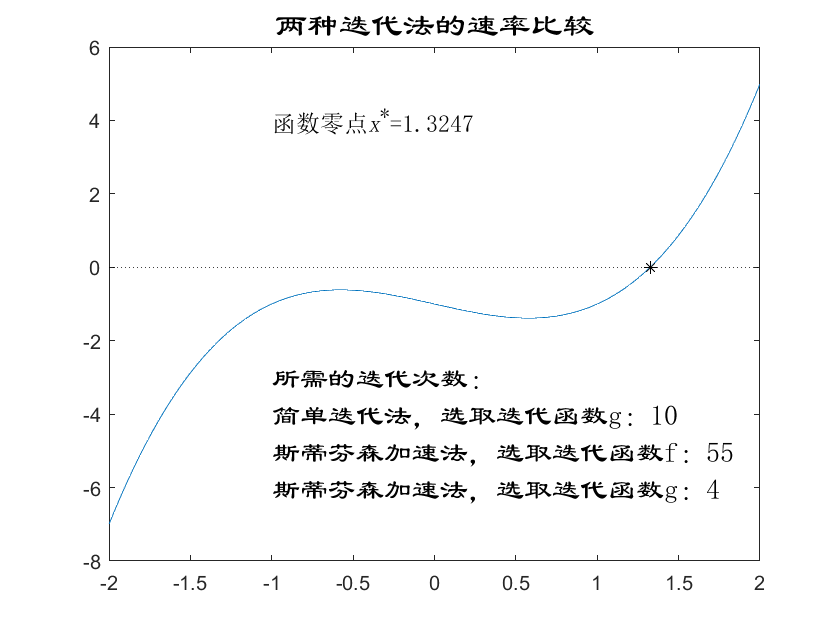

plot(x,f(x)-x,[-2,2],[0,0],'k:',x2,f(x2)-x2,'k*')  % 绘制图形
text(-1,4,['函数零点{\itx}^*=',num2str(x2)],...
    'fontname','宋体','fontsize',12)  % 添加标注
h(1)=text(-1,-3,'所需的迭代次数：');
% h(2)=text(-1,-4,['简单迭代法，选取迭代函数f：',num2str(iter1)]);
h(2)=text(-1,-4,['简单迭代法，选取迭代函数g：',num2str(iter2)]);
h(3)=text(-1,-5,['斯蒂芬森加速法，选取迭代函数f：',num2str(iter3)]);
h(4)=text(-1,-6,['斯蒂芬森加速法，选取迭代函数g：',num2str(iter4)]);
title('\fontname{隶书}\fontsize{16}两种迭代法的速率比较');  % 添加标题
set(h,'fontname','隶书','fontsize',14)  % 设置标注字体字号

**结论：**

**1、Steffensen加速法的收敛速度明显比简单不动点迭代法的速度快；**

**2、即使简单不动点迭代法不收敛，Steffensen加速迭代法仍可能收敛。**

# 注意：Steffensen加速法迭代步进大，如果f(x)非单调，可能跳过离得最近的根，搜索到相对远的根。

验证Steffensen加速法性能。

f=@(x)sin(x)-x.^2+0.5; % 定义函数表达式
x=-0.8:0.01:1;
[xx,iter,X]=steffensonfixpt(f,1.5,1e-8)  % Steffenson法求根

xx = -0.7547

iter = 4

X =    -0.7497
   -0.7548
   -0.7547
   -0.7547


xx,iter,X

xx = -0.7547

iter = 4

X =    -0.7497
   -0.7548
   -0.7547
   -0.7547


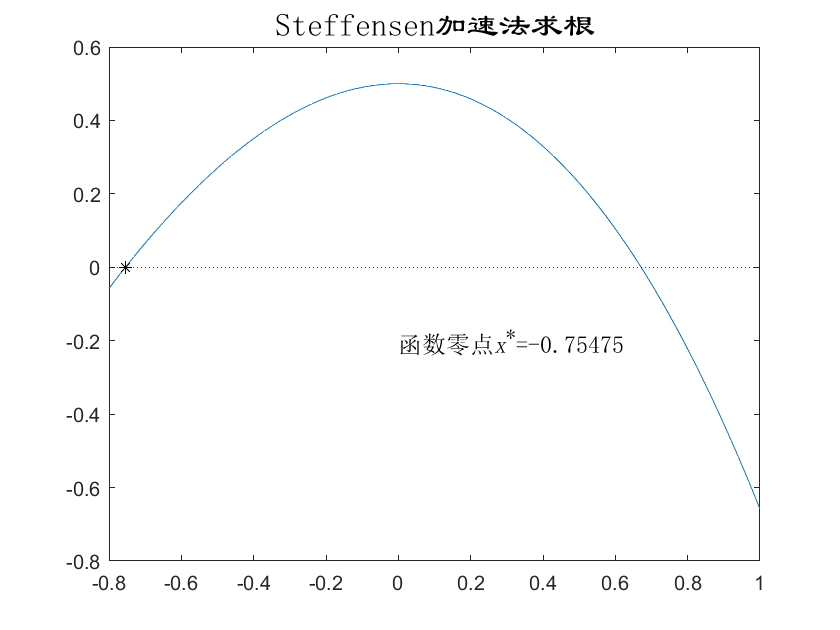

plot(x,sin(x)-x.^2-x+0.5,[-0.8,1],[0,0],'k:',...
    xx,f(xx)-xx,'k*')  % 绘制图形
text(0,-0.2,['函数零点{\itx}^*=',num2str(xx)],...
    'fontname','宋体','fontsize',12)  % 添加标注
title('\fontname{隶书}\fontsize{16}Steffensen加速法求根')  % 添加标题

### 9.3 牛顿法

用简单迭代法求解方程的根时，若迭代函数构造不好，则会影响收敛速度，甚至迭代格式还有可能发散。

为了选择一个迭代函数能够保证迭代序列收敛，引入牛顿迭代法。

#### 9.3.1 牛顿迭代法基本原理

牛顿迭代法的本质是一种线性化方法，其基本思想是将非线性方程f(x)=0逐步归结为某种线性方程来求解。

设方程f(x)=0有近似根$x_k$，将函数f(x)在点$x_k$处展开，则有


$$\mathrm{f}{\left(x\right)}\approx f{\left(x_k \right)}+f^{\prime } {\left(x_k \right)}{\left(x-x_k \right)}$$


于是，方程f(x)=0就可以近似表示为$f{\left(x_k \right)}+f^{\prime } {\left(x_k \right)}{\left(x-x_k \right)}=0$

对该方程求解，得到

该迭代公式即为 牛顿迭代公式。

$x_{k+1}$是点${\left(x_k ,f\left(x_k \right)\right)}$处y=f(x)的切线$\frac{f\left(x\right)-f\left(x_k \right)}{x-x_k }=f^{\prime } \left(x_k \right)$与x轴交点的横坐标。

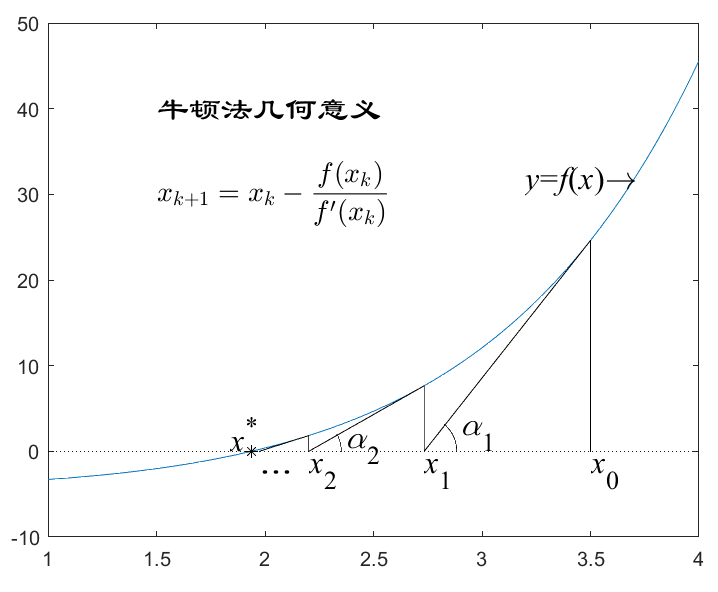

#### 9.3.2 牛顿迭代法的执行流程与实现

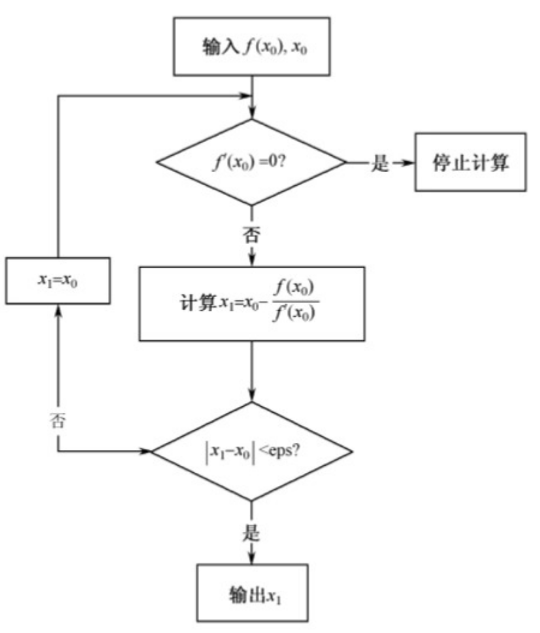 

**牛顿迭代法代码实现：**

function [x,iter,X]=newton(fun,x0,eps,maxiter)

% Newton法求解非线性方程的根

% 输入参数：

%      ---fun：迭代函数

%      ---x0：初始迭代点

%      ---eps：精度要求，默认值为1e-6

%      ---maxiter：最大迭代次数，默认值为1e4

% 输出参数：

%      ---x：非线性方程的近似根

%      ---iter：迭代次数

%      ---X：每一步迭代的结果

if nargin<2,error('输入参数至少需要2个！'),end

if nargin<3|isempty(eps),eps=1e-6;end

if nargin<4|isempty(maxiter),maxiter=1e4;end

k=0;err=1;

while abs(err)>eps

    k=k+1;

    [fx0,dfx0]=feval(fun,x0);

    if dfx0==0

        error('f(x)在x0处的导数为0，停止计算')

    end

    x1=x0-fx0/dfx0;

    err=x1-x0;

    x0=x1;

    X(k)=x1;

end

if k>=maxiter

    error('迭代次数超限，迭代失败！')

end

x=x1;iter=k;X=X';

====================================

**【例】使用牛顿迭代法求解 例1 **


x=0:0.01:2;
[xx,iter,X]=newton(@f1,1,1e-8)  % Newton法求根

xx = 1.2995

iter = 6

X =     1.1869
    1.2703
    1.2974
    1.2995
    1.2995
    1.2995


xx = 1.2995

iter = 6

X =     1.1869
    1.2703
    1.2974
    1.2995
    1.2995
    1.2995


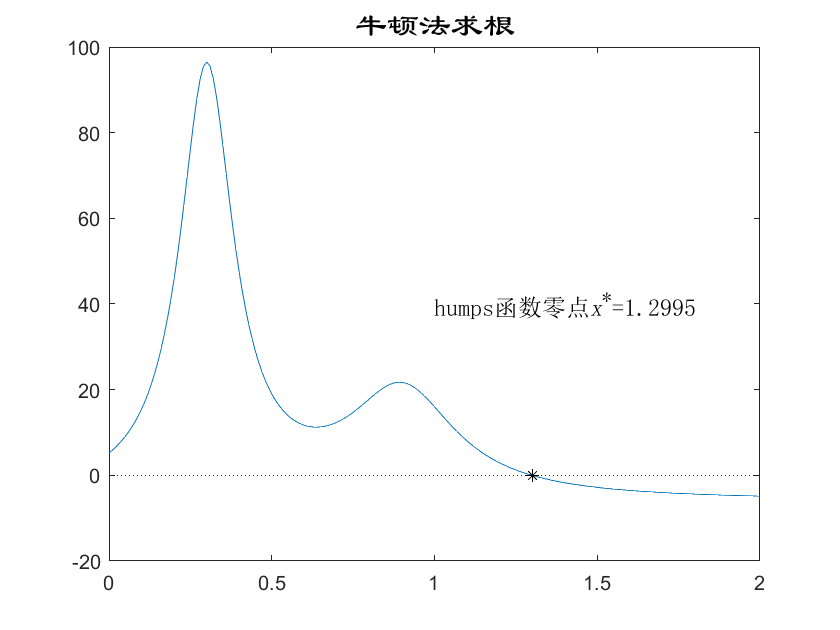

plot(x,f1(x),[0,2],[0,0],'k:',xx,f1(xx),'k*')  % 绘制图形
text(1,40,['humps函数零点{\itx}^*=',num2str(xx)],...
    'fontname','宋体','fontsize',12)  % 添加标注
title('\fontname{隶书}\fontsize{16}牛顿法求根')  % 添加标题

#### 9.3.3 牛顿迭代法的变形

**牛顿迭代法的优点是对单根收敛速度较快，不足之处在于：**

**1、初始近似值x0只有在根**$x^*$**附件才能保证迭代收敛，如果x0给得不合适，迭代可能不收敛；**

**2、每迭代1次，除要计算**$f\left(x_k \right)$**外，还需计算**$f^{\prime } \left(x_k \right)$**的值，如果函数f(x)比较复杂，那么计算**$f^{\prime } \left(x_k \right)$**的工作量就可能比较大。**

**3、针对重根情况，牛顿迭代法是线性收敛的，迭代速度慢。**

针对以上问题，提出以下改进算法：

**1、牛顿下山法**

牛顿下山法 = “牛顿法” + “下山法”

下山法： 在迭代过程中，为了防止迭代发散，对迭代过程进行限制，$\left| f(x_{k+1})\right|<\left|f(x_k)\right|$，使其数值稳定下降。

引入**下山因子**$\lambda \left(0<\lambda \le 1\right)$，将迭代格式改写为：


$$x_{k+1} =x_k -\lambda \frac{f\left(x_k \right)}{f^{\prime } \left(x_k \right)}$$


$\lambda$值的选取没有具体的公式课用，一般都用试算法，常用$\lambda =1，\frac{1}{2}，\frac{1}{4}，\ldotp \ldotp \ldotp \left(\lambda \ge \lambda_0 \right)$，$\lambda_0$为规定的$\lambda$的正的下界，迭代取值，

直至使得$\left| f(x_{k+1})\right|<\left|f(x_k)\right|$，确定迭代值$x_{k+1}$，同时将$\lambda$恢复为1。

====牛顿下山法代码实现过程========

function [x,iter,X]=newton_down(fun,x0,eps,maxiter)

% Newton下山法求解非线性方程的根

% 输入参数：

%      ---fun：迭代函数

%      ---x0：初始迭代点

%      ---eps：精度要求，默认值为1e-6

%      ---maxiter：最大迭代次数，默认值为1e4

% 输出参数：

%      ---x：非线性方程的近似根

%      ---iter：迭代次数

%      ---X：每一步迭代的结果

if nargin<2,error('输入参数至少需要2个！'),end

if nargin<3|isempty(eps),eps=1e-6;end

if nargin<4|isempty(maxiter),maxiter=1e4;end

k=1;tol=1;

while abs(tol)>eps

    lambda=1;

    [fx0,dfx0]=feval(fun,x0);

    x1=x0-lambda*fx0/dfx0;

    [fx1,dfx1]=feval(fun,x1);

    while abs(fx1)>=abs(fx0) 

        lambda=lambda/2;  % 更新lambda

        x1=x0-lambda*fx0/dfx0;  % 牛顿下山迭代

        [fx1,dfx1]=feval(fun,x1);

        x0=x1;

    end

    tol=fx1/dfx1;

    k=k+1;

    x0=x1;

    X(k)=x1;

End

if k==maxiter

    error('迭代次数超限，迭代失败！')

end

x=x1;iter=k;X=X';

===================

【例】 用牛顿下山法重新求解  例1 （humps函数）

x = 0:0.01:2;
[xx,iter,X]=newton_down(@f1,1,[],100)  % 牛顿下山法求根

xx = 1.2995

iter = 6

X =          0
    1.1869
    1.2703
    1.2974
    1.2995
    1.2995


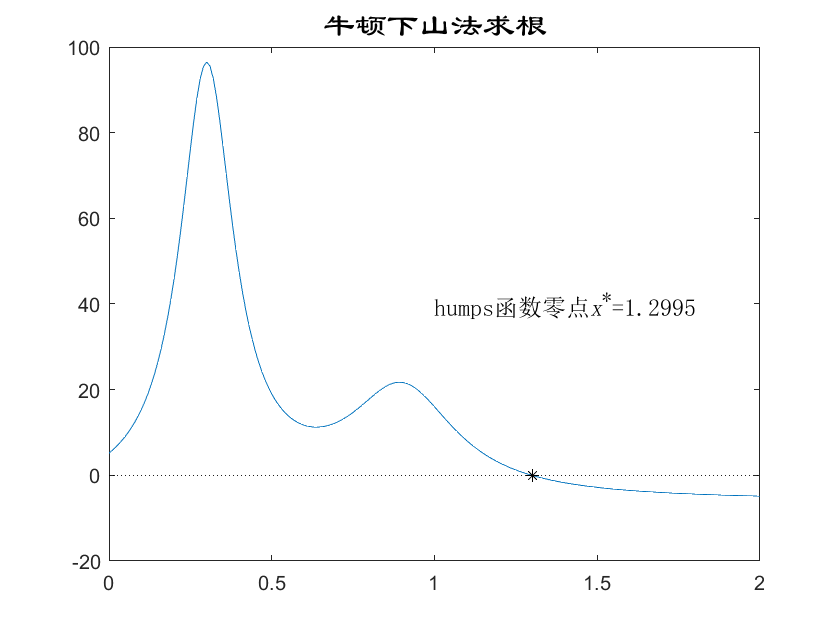

plot(x,f1(x),[0,2],[0,0],'k:',xx,f1(xx),'k*')  % 绘制图形
text(1,40,['humps函数零点{\itx}^*=',num2str(xx)],...
    'fontname','宋体','fontsize',12)  % 添加标注
title('\fontname{隶书}\fontsize{16}牛顿下山法求根')  % 添加标题

**2、 割线法**

解决牛顿法中的导数计算问题： 用后向有限差分来近似导数计算。


$$f^{\prime } \left(x_k \right)=\frac{f\left(x_k \right)-f\left(x_{k-1} \right)}{x_k -x_{k-1} }$$


从而得到迭代公式

$x_{k+1} =x_k -\frac{x_k -x_{k-1} }{f\left(x_k \right)-f\left(x_{k-1} \right)}f\left(x_k \right)$     该公式即为割线法的迭代公式。

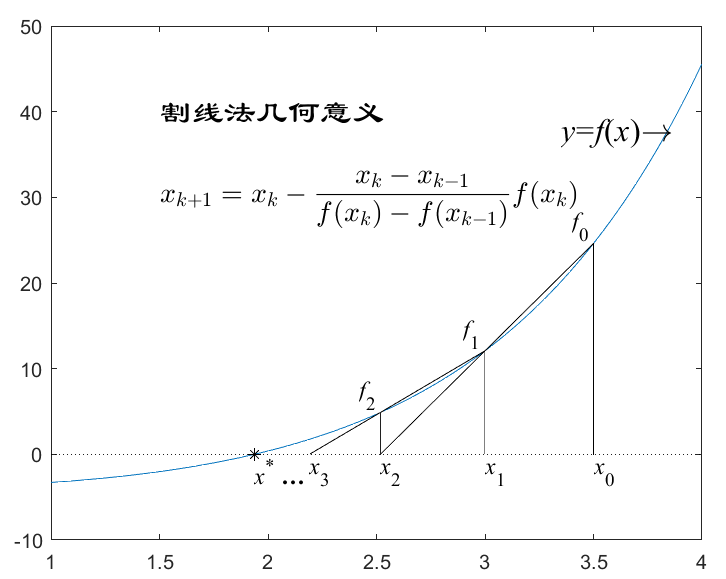

============ **割线法代码实现** ====================

function [x,iter,X]=secant(fun,x0,x1,eps,maxiter)

% 割线法求解非线性方程的根

% 输入参数：

%      ---fun：迭代函数

%      ---x0,x1：初始迭代点

%      ---eps：精度要求，默认值为1e-6

%      ---maxiter：最大迭代次数，默认值为1e4

% 输出参数：

%      ---x：非线性方程的近似根

%      ---iter：迭代次数

%      ---X：每一步迭代的结果

if nargin<3,error('输入参数至少需要3个！'),end

if nargin<4|isempty(eps),eps=1e-6;end

if nargin<5|isempty(maxiter),maxiter=1e4;end

f0 = feval(fun,x0); % 计算x0处的函数值

f1 = feval(fun,x1); % 计算x1处的函数值

k=0;

while abs(x1-x0)>eps

    k=k+1;

    x2=x1-f1*(x1-x0)/(f1-f0);

    f0=f1;

    x0=x1;x1=x2;

    f1 = feval(fun,x1); % 计算x1处的函数值

    X(k)=x2;

end

if k==maxiter

    error('迭代次数超限，迭代失败！')

end

x=x2;iter=k;X=X';

===== **实例** ==============

【例】 用割线法求解 1 hunps函数的根

求解代码：

x=0:0.01:2;
[xx,iter,X]=secant(@humps,1.5,1,1e-8)  % 割线法求根

xx = 1.2995

iter = 8

X =     1.4253
    1.3770
    1.2715
    1.3054
    1.3000
    1.2995
    1.2995
    1.2995


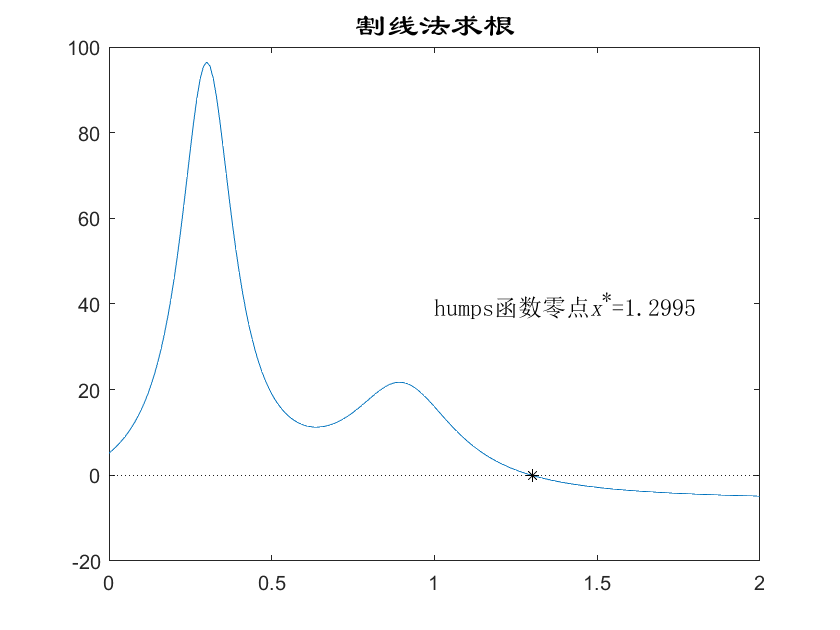

plot(x,humps(x),[0,2],[0,0],'k:',xx,humps(xx),'k*')  % 绘制图形
text(1,40,['humps函数零点{\itx}^*=',num2str(xx)],...
    'fontname','宋体','fontsize',12)  % 添加标注
title('\fontname{隶书}\fontsize{16}割线法求根')  % 添加标题

**3、 Steffenson法**

Steffeson法的导数近似方法：


$$f^{\prime } \left(x_k \right)\approx \frac{f\left(x_k +f\left(x_k \right)\right)-f\left(x_k \right)}{f\left(x_k \right)}$$


则迭代公式为：

========  代码实现 ==================

function [x,iter,X] = steffenson(fun,x0,eps,maxiter)

% Steffenson法求解非线性方程的根

% 输入参数：

%      ---fun：迭代函数

%      ---x0：初始迭代点

%      ---eps：精度要求，默认值为1e-6

%      ---maxiter：最大迭代次数，默认值为1e4

% 输出参数：

%      ---x：非线性方程的近似根

%      ---iter：迭代次数

%      ---X：每一步迭代的结果

if nargin<2,error('输入参数至少需要2个！'),end

if nargin<3|isempty(eps),eps=1e-6;end

if nargin<4|isempty(maxiter),maxiter=1e4;end

k=0;err=1;

while abs(err)>eps;

    k=k+1;

    f0 = feval(fun,x0); % 计算x0处的函数值

    x1=x0-f0^2/(feval(fun,x0+f0)-f0);  % Steffenson法迭代公式

    err=x1-x0;

    x0 = x1; % 更新x0数值

    X(k)=x1;

end

x=x1;iter=k;X=X';

**4、 牛顿修正法**

若$x^*$满足 $f\left(x\right)={\left(x-x^* \right)}^m g\left(x\right)$ , 其中m>1, g(x)有二阶导数且g($\left(x^* \right)\not= 0$，则称$x^*$是方程的m重根。

在m重根方程根的数值求解过程中可以考虑函数


$$u\left(x\right)=\frac{f\left(x\right)}{f^{\prime } \left(x\right)}$$


若$x^*$是方程f(x) = 0的m重根，则$x^*$是方程u(x) = 0的单根，这样就可以对方程u(x)=0使用牛顿迭代法。

迭代公式为：

$x_{k+1} =x_k -\frac{u\left(x_k \right)}{u^{\prime } \left(x_k \right)}=x_k -\frac{f\left(x_k \right)f^{\prime } \left(x_k \right)}{{\left\lbrack f^{\prime } \left(x_k \right)\right\rbrack }^2 -f\left(x_l \right)f^{\prime^{\prime } } \left(x_k \right)}$        (k=0,1,2,...)

========== 代码实现 =============

function [x,iter,X]=newton_reroot(fun,x0,eps,maxiter)

% Newton修正法(重根情形)求解非线性方程的根

% 输入参数：

%      ---fun：迭代函数

%      ---x0：初始迭代点

%      ---eps：精度要求，默认值为1e-6

%      ---maxiter：最大迭代次数，默认值为1e4

% 输出参数：

%      ---x：非线性方程的近似根

%      ---iter：迭代次数

%      ---X：每一步迭代的结果

if nargin<2,error('输入参数至少需要2个！'),end

if nargin<3|isempty(eps),eps=1e-6;end

if nargin<4|isempty(maxiter),maxiter=1e4;end

k=0;err=1;

while abs(err)>eps

    k=k+1;

    [fx0,dfx0,d2fx0]=feval(fun,x0);

    x1=x0-fx0*dfx0/(dfx0^2-fx0*d2fx0);  % 重根情形迭代公式

    err=x1-x0;  % 相邻两次迭代值的差值

    x0=x1;  % 更新x0

    X(k)=x1;

end

if k==maxiter

    error('迭代次数超限，迭代失败！')

end

x=x1;iter=k;X=X';

=======  实例4-7  ==================

分别利用牛顿法和牛顿修正法求解下面多项式方程在2附近的根

===** 代码实现**：

x0=2;
x=0.5:0.1:3;
[x1,iter1,X1]=newton_reroot(@fun1,x0)  % 重根情形的求解

x1 = 1.5600

iter1 = 4

X1 =     1.5893
    1.5601
    1.5600
    1.5600


[x2,iter2,X2]=newton(@fun1,x0)  % 牛顿法求根

x2 = 1.5600

iter2 = 33

X2 =     1.8444
    1.7462
    1.6827
    1.6412
    1.6139
    1.5958
    1.5838
    1.5759
    1.5706
    1.5670


plot(x,fun1(x),'k',[0.5 3],[0 0],'k:',x1,fun1(x1),'k*')  % 绘制图形
h(1)=text(1.5,2,['方程的根{\fontname{times}\itx}^*=',num2str(x1)]);  % 添加标注
h(2)=text(0.8,-2,['牛顿修正法迭代次数：',num2str(iter1)]);  % 添加标注
h(3)=text(0.8,-8,[blanks(4),'牛顿法迭代次数：',num2str(iter2)]);  % 添加标注
h(4)=title('牛顿法与牛顿修正法比较')  % 添加标题

h =   1×4 Text 数组:

    Text    Text    Text    Text


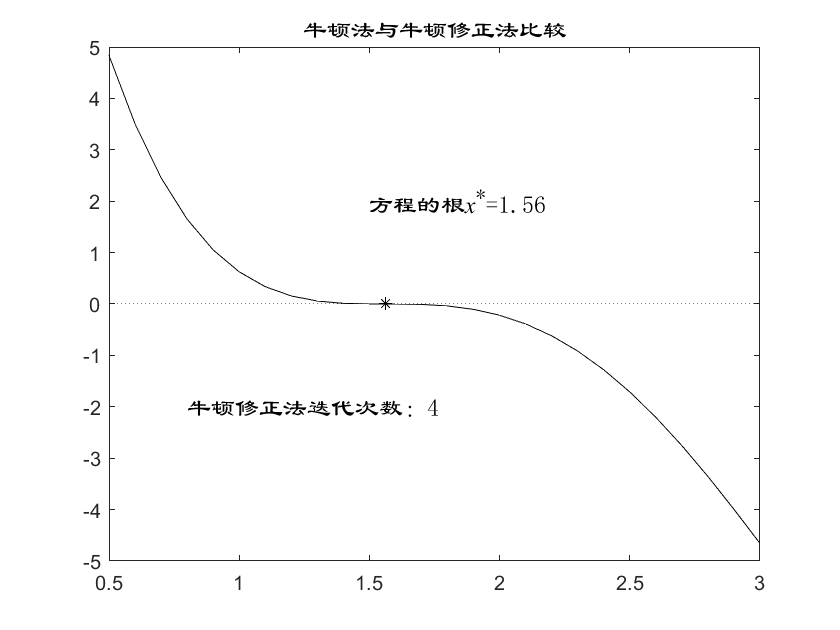

set(h,'fontname','隶书','fontsize',12)  % 设置字号与字体

### 9.4 非线性方程组的求解

非线性方程组可以看做非线性方程f(x)=0的推广，而非线性方程就是非线性方程组的特例。

非线性方程组的一般数学描述为


$${\left\{\begin{array}{c}
f_1 {\left(x_1 ,x_2 ,\dots ,x_n \right)}=0\\
f_2 {\left(x_1 ,x_2 ,\dots ,x_n \right)}=0\\
\dots \\
f_n {\left(x_1 ,x_2 ,\dots ,x_n \right)}=0
\end{array}\right)}$$


为叙述方便，记：$x={\left(x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_n \right)}^T$, $F={\left(f_1 ,f_2 ,\ldotp \ldotp \ldotp f_n \right)}^T$

非线性方程组可写为


$$F\left(x\right)=0$$


#### 9.4.1 牛顿法及其代码实现

非线性方程组的求法有很多，此处仅对使用牛顿法求解非线性方程组的根进行学习。

将多元向量函数F(x) 在点$x^{\left(k\right)}$处展开


$$F\left(x\right)\approx F\left(x^{\left(k\right)} \right)+F^{\prime } \left(\left.x^{\left(k\right)} \right)\left(x-x^{\left(k\right)} \right)\right)$$


其中，$F^{\prime } \left(x\right)$是F(x)的Jacobi矩阵

因此，可以得到求解非线性方程组的迭代方程

$x^{\left(k+1\right)} =x^{\left(k\right)} -{\left\lbrack F^{\prime } \left(x^{\left(k\right)} \right)\right\rbrack }^{-1} F\left(x^{\left(k\right)} \right)$     k=0,1,2,...

==== 流程图 ============

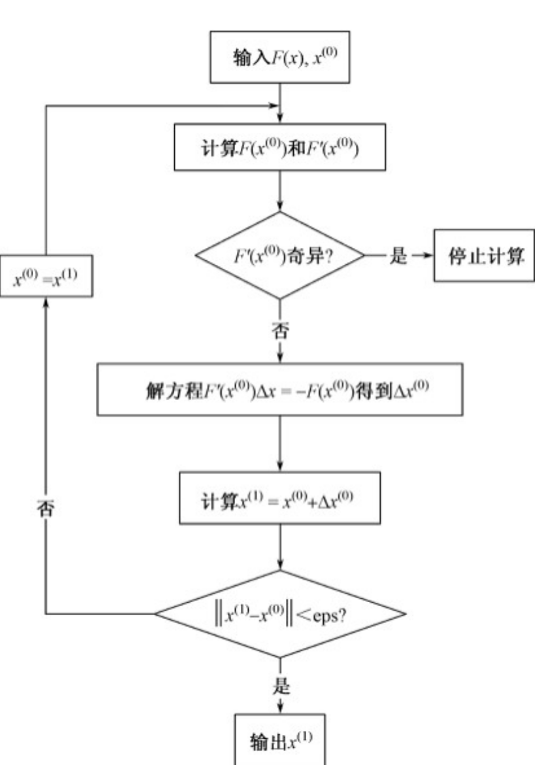

====  **代码实现 **=======

源代码文件：newtong.m

function [x,iter,X]=newtong(fun,x0,eps,maxiter)

% Newton法求解非线性方程组的根

% 输入参数：

%      ---fun：迭代函数

%      ---x0：初始迭代点向量

%      ---eps：精度要求，默认值为1e-6

%      ---maxiter：最大迭代次数，默认值为1e4

% 输出参数：

%      ---x：非线性方程的近似解向量

%      ---iter：迭代次数

%      ---X：每一步迭代的结果

if nargin<2,error('输入参数至少需要2个！'),end

if nargin<3|isempty(eps),eps=1e-6;end

if nargin<4|isempty(maxiter),maxiter=1e4;end

k=0;err=1;

while err>eps

    k=k+1;

    [fx0,J]=feval(fun,x0);  % 求函数fun的值和jacobi矩阵

    x1=x0-J\fx0;  % 牛顿法迭代公式

    err=norm(x1-x0);

    x0=x1;

    X(k,:)=x1;

end

if k==maxiter

    error('迭代次数超限，迭代失败！')

end

x=x1;iter=k;

========== **实例** ======

【例】 利用牛顿法求解下面的非线性方程组的解（初始迭代点取为 (-5,-5) ).


$$\left\lbrace \begin{array}{cc}
2x_1 -x_2 =e^{-x_1 }  & \\
-x_1 +2x_2 =e^{-x_2 }  & 
\end{array}\right.$$


==** 代码实现**


x0 = [-5; -5];
[x,iter,X]=newtong(@fg,x0)  % 牛顿法求根

x =     0.5671
    0.5671


iter = 9

X =    -3.9732   -3.9732
   -2.9183   -2.9183
   -1.8200   -1.8200
   -0.7057   -0.7057
    0.1970    0.1970
    0.5397    0.5397
    0.5670    0.5670
    0.5671    0.5671
    0.5671    0.5671


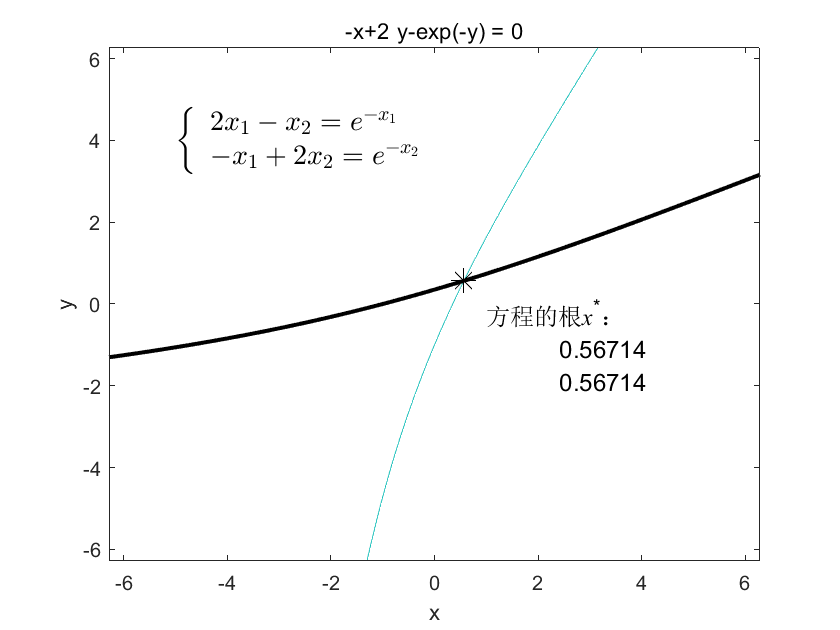

 
 Func-count    x          f(x)             Procedure
    2               2      -4.85517        initial
    3               2      -4.85517        interpolation
    4         1.74034       -4.1801        interpolation
    5         1.38618      -1.54123        bisection
    6         1.38618      -1.54123        interpolation
    7         1.31752     -0.377512        interpolation
    8         1.29852     0.0226319        interpolation
    9          1.2996   -0.00107861        interpolation
   10         1.29955  -2.91641e-06        interpolation
   11         1.29955   1.21059e-12        interpolation
   12         1.29955             0        interpolation
 
在区间 [0, 2] 中发现零


xx = 1.2995

fval = 0

exitflag = 1

output = 包含以下字段的 struct :
    intervaliterations: 0
            iterations: 10
             funcCount: 12
             algorithm: 'bisection, interpolation'
               message: '在区间 [0, 2] 中发现零'


ezplot('2*x-y-exp(-x)')  % 绘制第一个方程的曲线图
hold on  % 图形保持
h=ezplot('-x+2*y-exp(-y)');  % 绘制图形
set(h,'Color','k','LineWidth',2)  % 设置图形的线宽
plot(x(1),x(2),'k*','MarkerSize',12)  % 绘制零点
text(1,-1,strjust(char('方程的根{\fontname{times}\itx}^*：',num2str(x)),'center'),'fontsize',12)
text(-5,4,'$$\left\{\begin{array}{l}2{x_1}-{x_2}={e^{-{x_1}}}\\-{x_1}+2{x_2}={e^{-{x_2}}}\\\end{array}\right.$$','interpreter','latex','fontsize',14)  % 添加标注

#### 9.4.2 非线性方程的MATLAB函数求解

MATLAB优化工具箱提供了两个函数： fzero() 和 fsolve() 函数，分别用来求解非线性方程和非线性方程组的根。

**1、fzero() 函数**

**作用：求解单变量非线性方程的根。**

调用格式：  [x, fval, exitflag, output] = fzero(fun,x0,options, p1,p2,...)

`options` **-** **求解过程的选项**

通常使用 `optimset` 创建的结构体

求解过程的选项，指定为结构体。使用 [`optimset`](https://localhost:31515/static/help/matlab/ref/optimset.html) 创建或修改 `options` 结构体。`fzero` 使用下列 `options` 结构体字段。

`Display`

显示级别：

- `'off'` 不显示输出。

- `'iter'` 在每次迭代时显示输出。

- `'final'` 仅显示最终输出。

- `'notify'`（默认值）仅在函数未收敛时显示输出。

`FunValCheck`

检查目标函数值是否有效。

- 当目标函数返回的值是 `complex`、`Inf` 或 `NaN` 时，`'on'` 显示错误。

- 默认值 `'off'` 不会显示错误。

`OutputFcn`

以函数句柄或函数句柄的元胞数组的形式来指定优化函数在每次迭代时调用的一个或多个用户定义函数。默认值是“无”(`[]`)。请参阅 [输出函数](https://localhost:31515/static/help/matlab/math/output-functions.html)。

`PlotFcns`

绘制算法执行过程中的各个进度测量值。从预定义绘图中选择，或者自行编写。传递函数句柄或函数句柄的元胞数组。默认值是“无”(`[]`)。

- `@optimplotx` 绘制当前点。

- `@optimplotfval` 绘制函数值。

有关编写自定义绘图函数的信息，请参阅[绘图函数](https://localhost:31515/static/help/matlab/math/plot-functions.html)。

`TolX`

关于正标量 `x` 的终止容差。默认值为 `eps` 2.2204e–16。

**示例： **`options = optimset('FunValCheck','on')`

**数据类型：** `struct`

=====【例】 使用fzero() 求解 humps函数 ===========

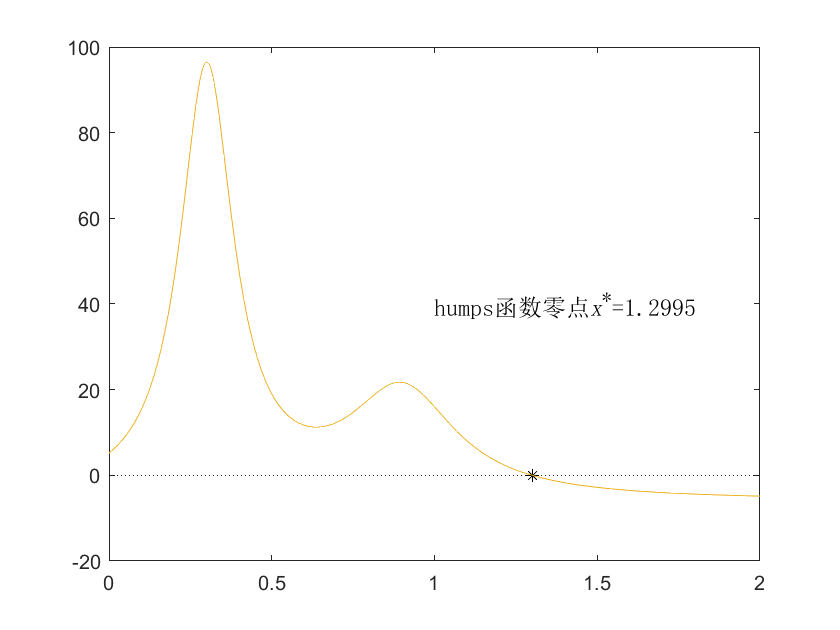

options = optimset('Display','iter');  % 调用myoutput函数以设置优化参数'OutputFcn'
[xx,fval, exitflag, output] = fzero(@humps,[0,2],options) % fzero函数求
% xx=fzero(@humps,1.5,options);
plot([0,2],[0,0],'k:',xx,humps(xx),'k*')  % 绘制图形

hold on
fplot(@humps,[0,2])
hold off
text(1,40,['humps函数零点{\itx}^*=',num2str(xx)],...
    'fontname','宋体','fontsize',12)  % 添加标注

# 基于初始点选取的函数多根求解

使用 ginput(n), 获取从图上鼠标点击的n个点的坐标

====  实例

求函数 $f\left(t\right)=e^{-\mathrm{at}} {\mathrm{sin}}^2 t-b\left|t\right|-1$在a=0.1, b=0.5时的零点。

求解步骤：

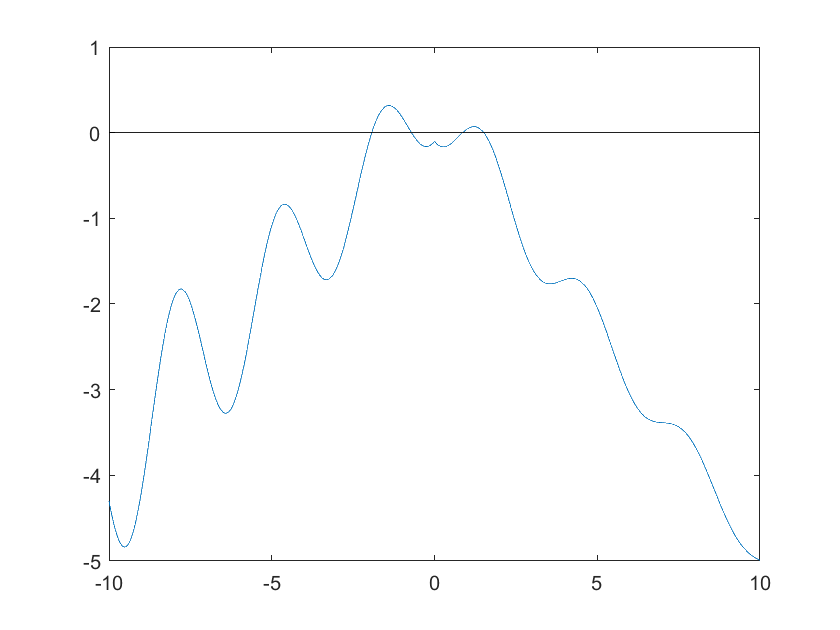

% example4_11
% 1、 划出函数曲线，初步判断根的数量
f=@(t,a,b)sin(t).^2.*exp(-a*t)-b*abs(t)-0.1;  % 定义函数表达式
t=-10:0.01:10;

a=0.1;b=0.5;
figure

错误使用 plotedit (line 123)
通过 uifigure 函数创建的图窗不支持该功能。有关详细信息，请参阅 App 设计工具中的图形支持。

出错 uisuspend (line 48)
            'ploteditEnable',        plotedit(fig,'getenabletools'), ...        

出错 

plot(t,f(t,a,b))  % 绘制图形
hold on
plot(xlim,[0 0],'k')  % 绘制直线y=0
%2、从图上可以看出有4个根，用鼠标在每个根附近点击选择求解初始点
[tt,yy]=ginput(4)  % 鼠标取点
for k=1:length(tt)
    x=fzero(@(t)f(t,a,b),tt(k));  % fzero函数求根
    % x=fzero(f,tt(k),[],a,b);
    T(k)=x;  % 将根依次存入向量T中
end
T

**2、fsolve（）**

作用：求解多变量非线性方程组的根。

调用格式： [x,fval, exitflag, output, jacobian] = fsolve(fun,x0,options, p1,p2,...)

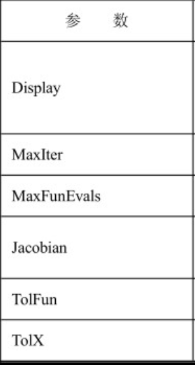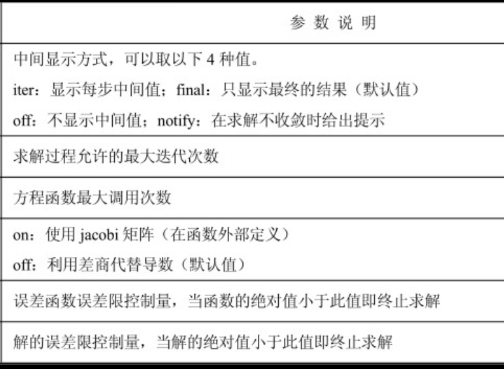

======== 实例  ===========

用fsolve（）求解非线性方程组

$\left\lbrace \begin{array}{cc}
2x_1 -x_2 =e^{-x_1 }  & \\
-x_1 +2x_2 =e^{-x_2 }  & 
\end{array}\right.$ 的根

% 代码实现：
fun=@(x)[2*x(1) - x(2) - exp(-x(1));


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3         47071.2                      2.29e+04               1
     1          6         12003.4              1       5.75e+03               1
     2          9         3147.02              1       1.47e+03               1
     3         12         854.452              1            388               1
     4         15         239.527              1            107               1
     5         18         67.0412              1           30.8               1
     6         21         16.7042              1           9.05               1
     7         24         2.42788              1           2.26               1
     8         27        0.032658       0.759511          0.206             2.5
     9         30     7.03149e-06       0.111927        0.00294             2.5
    10         33     3.29525e-13     0.001

x =     0.5671
    0.5671


fval = 	1.0e+-6 *

   -0.4059
   -0.4059


exitflog = 1

output = 包含以下字段的 struct :
       iterations: 10
        funcCount: 33
        algorithm: 'trust-region-dogleg'
    firstorderopt: 6.3612e-07
          message: '↵Equation solved.↵↵fsolve completed because the vector of function values is near zero↵as measured by the value of the function tolerance, and↵the problem appears regular as measured by the gradient.↵↵<stopping criteria details>↵↵Equation solved. The sum of squared function values, r = 3.295252e-13, is less than↵sqrt(options.FunctionTolerance) = 1.000000e-03. The relative norm of the gradient of r,↵6.361186e-07, is less than options.OptimalityTolerance = 1.000000e-06.↵↵'


jacobian =     2.5671   -1.0000
   -1.0000    2.5671


    -x(1) + 2*x(2) - exp(-x(2))];  % 利用匿名函数定义方程组
x0 = [-5; -5];  % 迭代初值
options=optimset('Display','iter');  % 设置优化参数显示每一步的迭代结果
% options=optimset;options.Display='iter';
[x,fval,exitflog,output,jacobian] = fsolve(fun,x0,options)  % fsolve函数求方程组的根

# 作业 

1、第2周贷款问题：

`你想买一套`300`万元的房子，首付`40%`，贷款20年，等额本息，已知月还款额为1.2万元，求贷款月利率为多少？`

`(1) 编写 结合牛顿下山法和割线法的综合迭代方法求解函数，调用后求解；`

`（2）使用steffenson法求解。`

`2、用牛顿法求解二元方程组的根`


$$\left\lbrace \begin{array}{cc}
x^2 \mathrm{cos2x}+y^2 \mathrm{syn2y}=1 & \\
x^3 +y^3 -6\mathrm{cos2xy}=-1 & 
\end{array}\right.$$


function [y,J]=fg(x)
    % 例4-9 非线性方程组
    % 函数文件描述，返回函数值和jacobi矩阵
    y=[2*x(1) - x(2) - exp(-x(1));
        -x(1) + 2*x(2) - exp(-x(2))];  % 计算函数值
    % 求Jacobi矩阵
    syms xx yy;  % 声明符号变量
    J=jacobian([2*xx-yy-exp(-xx);-xx+2*yy-exp(-yy)],[xx yy]);  % 求符号jacobi矩阵
    xx = x(1);
    yy = x(2);
    J=eval(J);  % 替换
    % J=subs(J,yy,x(2));  % 替换
end

function [y,dy] = f1(x)
% 例4-1 humps函数，返回函数值和一阶导数值
% 函数描述文件，主要功能是求解函数表达式的值及其导数值
    syms t
    y = 1./((t-.3).^2 +.01)+1./((t-.9).^2 +.04)-6;  % 计算函数值
    dy = diff(y);  % 求1阶导数
    t = x;
    dy = eval(dy);  % 求数值
    y = eval(y);
end

function [y,dy,d2y]=fun1(x)
    % 函数描述文件   例 4-7 求解函数代码
    syms t
    y=t.^4-(231*t.^3)/25 + (17901*t.^2)/625 -...
        (579501*t)/15625 + 6762366/390625;  % 计算函数
    dy=diff(y);
    d2y=diff(y,2);
    t = x;
    y = eval(y);
    dy=eval(dy);  % 一阶导数
    d2y=eval(d2y);  % 二阶导数
end